# Determine Minimum Required Gear Ratio for Fixed Ratio Applications

Copyright 2022 - 2023 The MathWorks, Inc.

To return to the main page within this repository, [click here](matlab:open('ElectricVehicleDesignOverview.html')).

### Determine Minimum Gear Ratio    

Drive units with fixed gear ratio are usually the most cost effective option for battery electric vehicle. To determine an appropriate fixed gear ratio, run a design of experiment (DoE) which covers a range of gear ratios and test cycle parameters. This example runs the motor thermal test bench for the DoE that is formed by combinations of array elements `gearRatio` and `testCycle. T`he test duration is attached to a test cycle. Therefore the elements of `runTime` are placed in the corresponding order of the elements defined in `testCycle`.

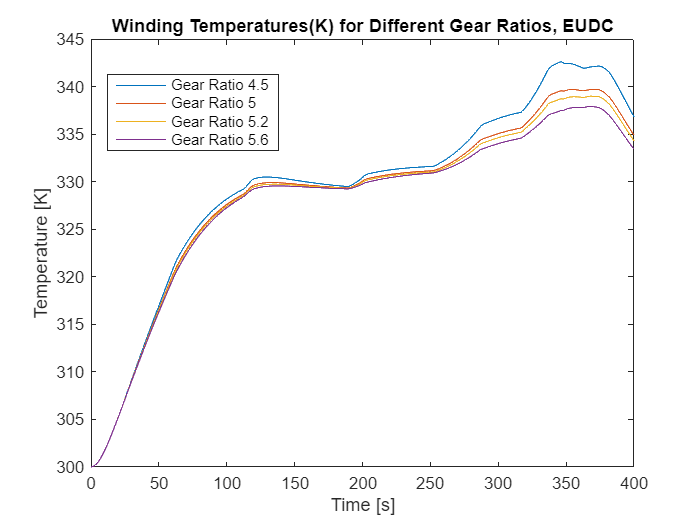

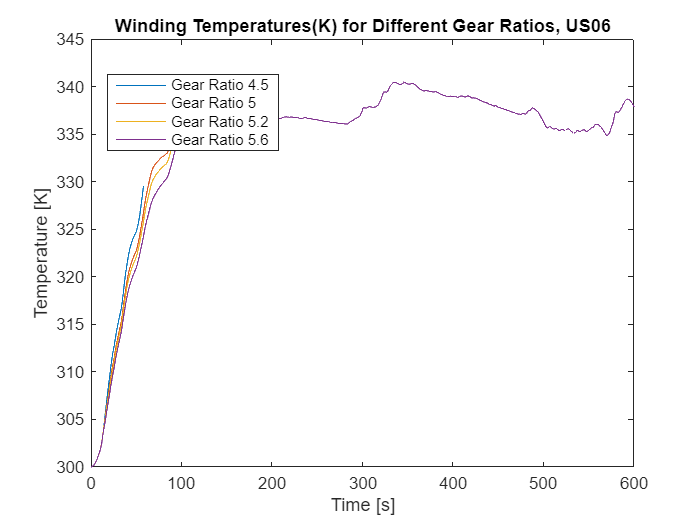

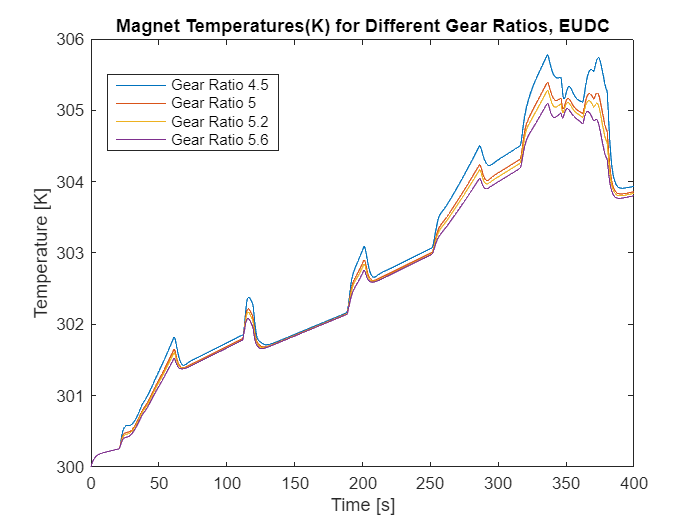

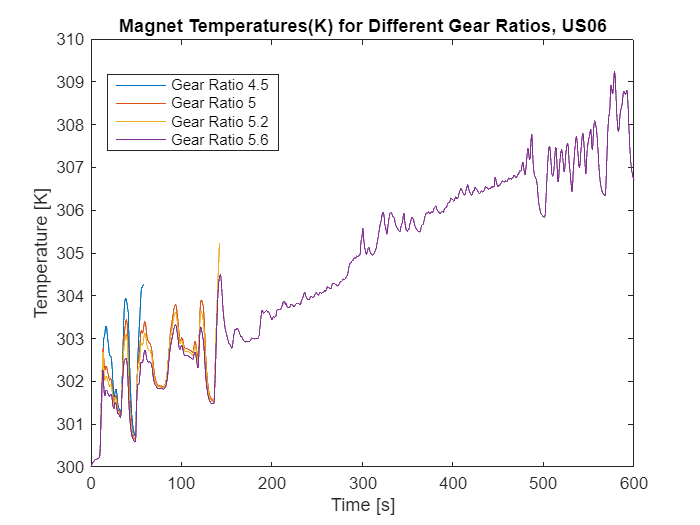

GearRatioDoEsummary = 4×2 table
                       EUDC      US06 
                      ______    ______

    Gear Ratio 4.5    "Pass"    "Fail"
    Gear Ratio 5      "Pass"    "Fail"
    Gear Ratio 5.2    "Pass"    "Fail"
    Gear Ratio 5.6    "Pass"    "Pass"


gearRatio = [4.5,5.0,5.2,5.6];% Gear Ratios 
testCycle = ["EUDC","US06"];% Name of the standard test cycle 
runTime = [400,600];% desired time in sec for which test. (If runTime > standard test time, then the test is repeted for exctra duration)
GearRatioDoEsummary = testThermalBenchRun(gearRatio,testCycle,runTime)

Each row of the table `GearRatioDoEsummary` shows the value of gear ratio and if they pass or fail in the test (failure criterion remains same as discussed in previous section). Temperature timeseries output of the simulations is stored in the MAT file `PMSMbatchRunTemp`. Function `PMSMplotMotTemperature` plots the magnet and winding temperatures. At around 300 sec, the winding temperature exceeds the threshold value of 473.15 K in the US06 run for all the gear ratios below 5.6.